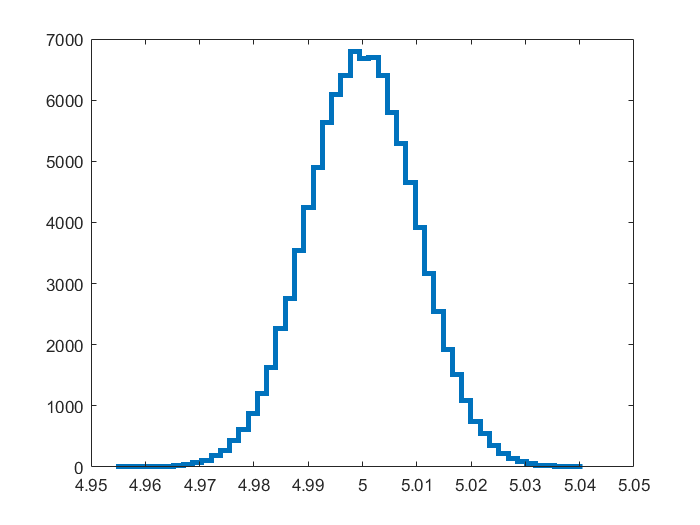

d = random('Normal', 5., 0.01, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([4.95,5.05])


n = normcdf(d, 5)

n =     0.4977    0.4997    0.5012    0.4987    0.4936    0.4976    0.4899    0.4912    0.4938    0.4996    0.4988    0.5059    0.5056    0.4946    0.5106    0.4959    0.4954    0.5053    0.4968    0.5044    0.5000    0.5064    0.5001    0.4974    0.4957    0.5010    0.4966    0.5034    0.5017    0.5005    0.4945    0.4967    0.5004    0.5019    0.5032    0.4965    0.5037    0.4954    0.5009    0.5035    0.5046    0.5051    0.5030    0.4988    0.4987    0.5027    0.5004    0.4993    0.4946    0.4967



norminv(.978) %outputs z value associated with the standard normal probability input

ans = 2.0141

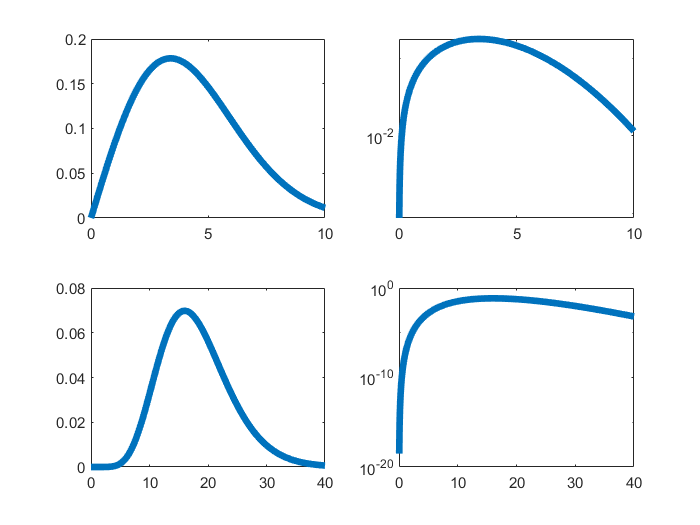


x = linspace(0,10,1000);
rayl = makedist("Rayleigh",'b',3.4);
subplot(2,2,2)
plot(x,pdf(rayl,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(2,2,1)
plot(x,pdf(rayl,x),"LineWidth",4);

x = linspace(0,40,1000);    
chisq = makedist("Gamma",'a',18/2.,'b',2.); %special case for Chi-squared
subplot(2,2,4)
plot(x,pdf(chisq,x),"LineWidth",4);
set(gca,'YScale','log')
subplot(2,2,3)
plot(x,pdf(chisq,x),"LineWidth",4);